# Ver 3 Network:

- Presynaptic neuron # fixed;

- Boundaries tape back

- LGN: Phase variant

- Adding complex cells

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo073121/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo071021/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

% load('NtWk_Archit.mat')
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
% N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_S_HC = 45; n_C_HC = 30; n_I_HC = 31; % per side of HC
N_S = n_S_HC^2 * N_HC^2; % neuron numbers In all
N_C = n_C_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
N_E = N_S+N_C; CplxR = N_C/N_E;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_S = Size_HC/n_S_HC; Size_C = Size_HC/n_C_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnS.X,NnS.Y] = V1Field_Generation(N_HC,1:N_S,'e',n_S_HC,n_I_HC);
[NnC.X,NnC.Y] = V1Field_Generation(N_HC,1:N_C,'e',n_C_HC,n_I_HC);
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');
%NnE.X = [NnS.X,NnC.X]; NnE.Y = [NnS.Y,NnC.Y];

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_S = n_S_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_C = n_C_HC^2 * (N_HC+2)^2; 
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnSex.X,NnSex.Y] = V1Field_Generation(N_HC+2,1:Nex_S,'e',n_S_HC,n_I_HC);
[NnCex.X,NnCex.Y] = V1Field_Generation(N_HC+2,1:Nex_C,'e',n_C_HC,n_I_HC);
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');

Now select complx cells

## Tuning NOW!!!

N_EE = 193; N_EI = 85; %*0.75
N_IE = 844; N_II = 84; %*0.75 Plan A:Original

CplxNEIncr = 253/N_EE; % Was 250 for 071021 simulation
EcplxInd = ismember(1:N_E, N_S+1:N_E); 

N_SS = N_EE * (1-CplxR);            N_SC = N_EE * (CplxR); 
N_CS = N_EE * (1-CplxR)*CplxNEIncr; N_CC = N_EE * (CplxR)*CplxNEIncr;
N_SI = N_EI;                        N_CI = N_EI; 
N_IS = N_IE * (1-CplxR);            N_IC = N_IE * (CplxR); 

## Get a mapping between original and extended spatial indexs

% From original to extended
SMap_Ori2Ext = find(NnSex.X>n_S_HC & NnSex.X<=4*n_S_HC ...
                  & NnSex.Y>n_S_HC & NnSex.Y<=4*n_S_HC);
CMap_Ori2Ext = find(NnCex.X>n_C_HC & NnCex.X<=4*n_C_HC ...
                  & NnCex.Y>n_C_HC & NnCex.Y<=4*n_C_HC);
IMap_Ori2Ext = find(NnIex.X>n_I_HC & NnIex.X<=4*n_I_HC ...
                  & NnIex.Y>n_I_HC & NnIex.Y<=4*n_I_HC);
% from extended back to original: fold
% E
SMap_Ext2Ori = FoldExMap2Ori(NnSex,NnS,SMap_Ori2Ext,N_S,n_S_HC);
CMap_Ext2Ori = FoldExMap2Ori(NnCex,NnC,CMap_Ori2Ext,N_C,n_C_HC);
% I
IMap_Ext2Ori = FoldExMap2Ori(NnIex,NnI,IMap_Ori2Ext,N_I,n_I_HC);
% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary
% EE
C_SS_Fix_Bd = ConnectionMat_FB_SimCplx(N_S,NnSex,Size_S, SMap_Ori2Ext, 1:N_S,...% 
                                       N_S,NnSex,Size_S, SMap_Ext2Ori, 1:N_S,...
                                       Peak_EE,SD_E,Dist_LB,1, round(N_SS));

Elapsed time is 9.377731 seconds.


C_SC_Fix_Bd = ConnectionMat_FB_SimCplx(N_S,NnSex,Size_S, SMap_Ori2Ext, 1:N_S,...% 
                                       N_C,NnCex,Size_C, CMap_Ext2Ori, 1:N_C,...
                                       Peak_EE,SD_E,Dist_LB,0, round(N_SC));

Elapsed time is 5.328324 seconds.


C_CS_Fix_Bd = ConnectionMat_FB_SimCplx(N_C,NnCex,Size_C, CMap_Ori2Ext, 1:N_C,...% 
                                       N_S,NnSex,Size_S, SMap_Ext2Ori, 1:N_S,...
                                       Peak_EE,SD_E,Dist_LB,0, round(N_CS));

Elapsed time is 4.360185 seconds.


C_CC_Fix_Bd = ConnectionMat_FB_SimCplx(N_C,NnCex,Size_C, CMap_Ori2Ext, 1:N_C,...% 
                                       N_C,NnCex,Size_C, CMap_Ext2Ori, 1:N_C,...
                                       Peak_EE,SD_E,Dist_LB,1, round(N_CC));

Elapsed time is 2.524245 seconds.


C_EE_Fix_Bd = [C_SS_Fix_Bd, C_SC_Fix_Bd; C_CS_Fix_Bd, C_CC_Fix_Bd];
% EI
C_SI_Fix_Bd = ConnectionMat_FB_SimCplx(N_S,NnSex,Size_S, SMap_Ori2Ext, 1:N_S,...
                                       N_I,NnIex,Size_I, IMap_Ext2Ori, 1:N_I,...
                                       Peak_I,SD_I,Dist_LB,0, round(N_SI));

Elapsed time is 6.067247 seconds.


C_CI_Fix_Bd = ConnectionMat_FB_SimCplx(N_C,NnCex,Size_C, CMap_Ori2Ext, 1:N_C,...
                                       N_I,NnIex,Size_I, IMap_Ext2Ori, 1:N_I,...
                                       Peak_I,SD_I,Dist_LB,0, round(N_CI));

Elapsed time is 2.613912 seconds.


C_EI_Fix_Bd = [C_SI_Fix_Bd; C_CI_Fix_Bd];
% IE
C_IS_Fix_Bd = ConnectionMat_FB_SimCplx(N_I,NnIex,Size_I, IMap_Ori2Ext, 1:N_I,...
                                       N_S,NnSex,Size_S, SMap_Ext2Ori, 1:N_S,...
                                       Peak_I,SD_E,Dist_LB,0, round(N_IS));

Elapsed time is 8.321853 seconds.


C_IC_Fix_Bd = ConnectionMat_FB_SimCplx(N_I,NnIex,Size_I, IMap_Ori2Ext, 1:N_I,...
                                       N_C,NnCex,Size_C, CMap_Ext2Ori, 1:N_C,...
                                       Peak_I,SD_E,Dist_LB,0, round(N_IC));

Elapsed time is 4.279288 seconds.


C_IE_Fix_Bd = [C_IS_Fix_Bd, C_IC_Fix_Bd];
% II
C_II_Fix_Bd = ConnectionMat_Fix_Boundary(N_I,NnIex,Size_I, IMap_Ori2Ext,...
                                         N_I,NnIex,Size_I, IMap_Ext2Ori,...
                                         Peak_I,SD_I,Dist_LB,1, round(N_II));

Elapsed time is 2.938944 seconds.



CMatAll = struct('C_EE_Fix_Bd',C_EE_Fix_Bd,...
                 'C_EI_Fix_Bd',C_EI_Fix_Bd,...
                 'C_IE_Fix_Bd',C_IE_Fix_Bd,...
                 'C_II_Fix_Bd',C_II_Fix_Bd);

### Checking presyn neurons to boundary neurons. Can jump

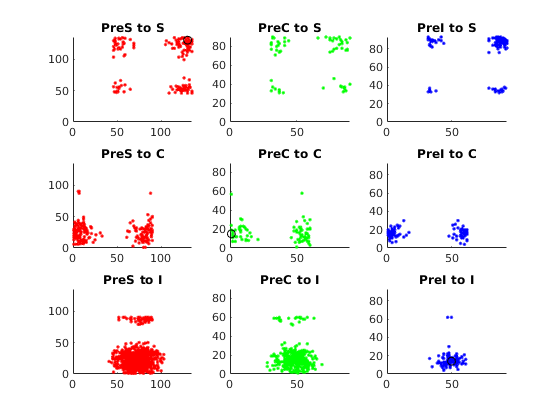

figure
% S cell as post
SX = 130; SY = 130;
SInd = find(NnS.X == SX & NnS.Y == SY);
PreSInd = find(C_SS_Fix_Bd(SInd,:));
PreCInd = find(C_SC_Fix_Bd(SInd,:));
PreIInd = find(C_SI_Fix_Bd(SInd,:));

subplot 331
hold on
%imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
scatter(SX,SY,'kO')
set(gca,'YDir','normal')
axis([0 n_S_HC * N_HC 0 n_S_HC * N_HC])
title('PreS to S')

subplot 332
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnC.X(PreCInd),NnC.Y(PreCInd), 'g.')
set(gca,'YDir','normal')
axis([0 n_C_HC * N_HC 0 n_C_HC * N_HC])
title('PreC to S')

subplot 333
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to S')

% C cell as post
CX = 1; CY = 15;
CInd = find(NnC.X == CX & NnC.Y == CY);
PreSInd = find(C_CS_Fix_Bd(CInd,:));
PreCInd = find(C_CC_Fix_Bd(CInd,:));
PreIInd = find(C_CI_Fix_Bd(CInd,:));

subplot 334
hold on
%imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
set(gca,'YDir','normal')
axis([0 n_S_HC * N_HC 0 n_S_HC * N_HC])
title('PreS to C')

subplot 335
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnC.X(PreCInd),NnC.Y(PreCInd), 'g.')
scatter(CX,CY,'kO')
set(gca,'YDir','normal')
axis([0 n_C_HC * N_HC 0 n_C_HC * N_HC])
title('PreC to C')

subplot 336
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to C')

% I cell as post
IX = 50; IY = 14;
IInd = find(NnI.X == IX & NnI.Y == IY);
PreSInd = find(C_IS_Fix_Bd(IInd,:));
PreCInd = find(C_IC_Fix_Bd(IInd,:));
PreIInd = find(C_II_Fix_Bd(IInd,:));

subplot 337
hold on
%imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
set(gca,'YDir','normal')
axis([0 n_S_HC * N_HC 0 n_S_HC * N_HC])
title('PreS to I')

subplot 338
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnC.X(PreCInd),NnC.Y(PreCInd), 'g.')
set(gca,'YDir','normal')
axis([0 n_C_HC * N_HC 0 n_C_HC * N_HC])
title('PreC to I')

subplot 339
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
scatter(IX,IY,'kO')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to I')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.530; 
rI_amb = 0.435; % was 0.5 for for 071021 simulation

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.8;  % was 1.6 for for 071021 simulation
S_II = 0.120; S_IE = S_II*0.153 * 1.6/1.8;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
N_Slgn = 4.75; N_Clgn = 1.25; N_Ilgn = 4.5;

lambda_E = 0.02*[N_Slgn*ones(N_S,1);N_Clgn*ones(N_C,1)]; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.02*N_Ilgn; 

## Network Simulation: BG

Elapsed time is 5.532935 seconds.
Elapsed time is 8.125748 seconds.
Elapsed time is 10.819073 seconds.
Elapsed time is 13.456923 seconds.
Elapsed time is 16.117854 seconds.
Elapsed time is 18.903594 seconds.
Elapsed time is 21.715535 seconds.
Elapsed time is 24.525062 seconds.


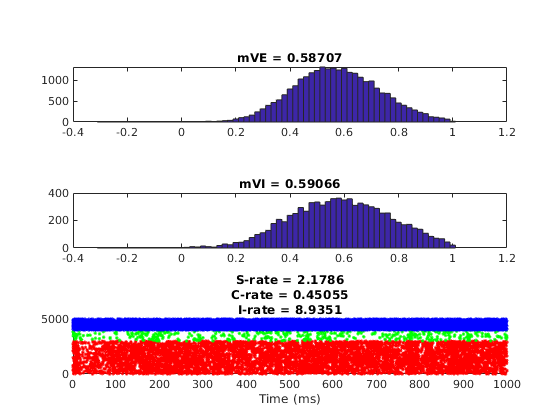

Elapsed time is 27.549223 seconds.


%% Network Simulation
T = 1000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.1; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.1; N_IEDly = floor(T_IEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% 
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
% N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
[InEs, InIs] = LargeNW_LoadIniState('Initials_L6.mat', [],N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = sparse(N_I,N_IEDly);
%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

S_Ind = 10000:13000; C_Ind = N_S:N_S+1000;
I_Ind = 3300:4300;
tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEnIEDelay(...
        RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
%         ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
%             ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
%             'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
%             ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
%             'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        %fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        scatterS = find(ismember(E_Sp(:,1),S_Ind));
        scatterC = find(ismember(E_Sp(:,1),C_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,S_Fire_Ind] = ismember(E_Sp(scatterS,1),S_Ind);
        [~,C_Fire_Ind] = ismember(E_Sp(scatterC,1),C_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        S_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),S_Ind));
        C_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),C_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        S_Rate = length(S_SpInd)/(WinSize/1000)/length(S_Ind);
        C_Rate = length(C_SpInd)/(WinSize/1000)/length(C_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
%         f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
%                                                     S_EE,S_EI,S_IE,S_II,p_EEFail,...
%                                                     lambda_E,S_Elgn,rE_amb,S_amb,...
%                                                     lambda_I,S_Ilgn,rI_amb,...
%                                                     S_EL6,S_IL6,rE_L6,rI_L6,...
%                                                     gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterS,2),S_Fire_Ind,'r.')
        scatter(E_Sp(scatterC,2),C_Fire_Ind+max(S_Fire_Ind),'g.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(S_Fire_Ind)+max(C_Fire_Ind),'b.');
        title({['S-rate = ' num2str(S_Rate)],['C-rate = ' num2str(C_Rate)],['I-rate = ' num2str(I_Rate)]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
       % ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        S_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),S_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(S_SpInd)/(WinSize/1000)/length(S_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(S_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(S_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(S_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

Elapsed time is 27.551676 seconds.



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [S_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .1; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .1; N_IEDly = floor(T_IEDly/dt); %% NOTE: Was both 0.5
T_EIDly = .1; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
          'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState('InSStr', InSStr,N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);      
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        tt = 0:dt:InpWin-dt;
        AdjlgnE = PhaseFRS(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
        AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                             + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                             + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                             + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                             + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.1; % Can't be too small for multiple phases
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        
        NWTrace(SampleInd).GE_I = GE_ITemp;
        NWTrace(SampleInd).GE_E = GE_ETemp;
        NWTrace(SampleInd).GI_I = GI_ITemp;
        NWTrace(SampleInd).GI_E = GI_ETemp;
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
        FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        % Precompute GE GI
        GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
        GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %                       

        GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
        GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %                       
        GE_ITemp(:,mVRecordInd) = GE_I;
        GE_ETemp(:,mVRecordInd) = GE_E;
        GI_ITemp(:,mVRecordInd) = GI_I;
        GI_ETemp(:,mVRecordInd) = GI_E;
        %record loop goes forward
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = [sprintf('DriveWkSp_Cplx_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 13.4266

FrECNow = 55.7605

FrINow = 83.0524

Elapsed time is 2.599048 seconds.


SampleInd = 3

FrESNow = 12.1888

FrECNow = 24.3802

FrINow = 63.2327

Elapsed time is 4.180923 seconds.


SampleInd = 4

FrESNow = 11.6774

FrECNow = 26.0123

FrINow = 62.8813

Elapsed time is 6.464318 seconds.


SampleInd = 5

FrESNow = 11.6488

FrECNow = 47.0173

FrINow = 77.6992

Elapsed time is 8.110160 seconds.


save([SaveFolder,'DriveWkSp_Cplx_SCSepa_Cconst_Conn.mat'],'CMatAll','EcplxInd');

### Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = [sprintf('DriveWkSp_Cplx_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    
%     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
%     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
%     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
%     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
    
%     GE_E = [GE_E, GE_ECurrent]; 
%     GE_I = [GE_I, GE_ICurrent];
%     GI_E = [GI_E, GI_ECurrent]; 
%     GI_I = [GI_I, GI_ICurrent];
    
end
load([SaveFolder text],'PhaseE');
load( 'DriveWkSp_Cplx_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

Check soome time dependency// cental hypercolum??

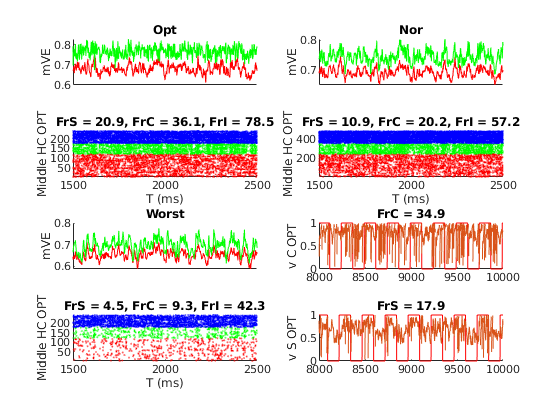

OptE = OD_E==1;           OptI = OD_I==1;
WorstE = OD_E==3;         WorstI = OD_I==3;
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1.25*n_S_HC & NnS.X<=1.75*n_S_HC;
MidRowS = NnS.Y>=1.25*n_S_HC & NnS.Y<=1.75*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1.25*n_C_HC & NnC.X<=1.75*n_C_HC;
MidRowC = NnC.Y>=1.25*n_C_HC & NnC.Y<=1.75*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1.25*n_I_HC & NnI.X<=1.75*n_I_HC;
MidRowI = NnI.Y>=1.25*n_I_HC & NnI.Y<=1.75*n_I_HC;
MidHCI= MidColI & MidRowI;

SOpt = find(OptE & ~EcplxInd);
scatterSOpt = find(ismember(SpE(:,1), SOpt));
[~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);

COpt = find(OptE & EcplxInd);
scatterCOpt = find(ismember(SpE(:,1), COpt));
[~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [1500 2500];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');  
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');  
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');  
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

### Plot Spatial maps: Plot

WinSize = 9000;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));


Determine On and Off t for Frs and mVs: 

Note, we get rid of the first 10ms of each interval

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
PhaseExc = 20;
mVPh = mod(repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), tMod);
OnOffmV = ~logical(floor(mVPh/MaxOnPhase)); % 1 for all on period, 0 for all off
OnmV  =  OnOffmV & ~(0< mVPh & mVPh<PhaseExc);
OffmV = ~OnOffmV & ~(MaxOnPhase< mVPh & mVPh<MaxOnPhase+PhaseExc);

SpPh = mod(PhaseE(SpE(:,1)) - T + SpE(:,2),tMod);
OnOffSpE =  ~logical(floor(SpPh/MaxOnPhase));
% OnSpE  =  OnOffSpE & ~(0<SpPh & SpPh<PhaseExc);
% OffSpE = ~OnOffSpE & ~(MaxOnPhase<SpPh & SpPh<MaxOnPhase+PhaseExc);
% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

% NnS.X = NnE.X(~EcplxInd); NnS.Y = NnE.Y(~EcplxInd);
% NnC.X = NnE.X(EcplxInd); NnC.Y = NnE.Y(EcplxInd);

FrERan = [0 55];
mVERan = [0.62 0.80];

Figure for ONOFF

First create an onoff vec for each spike

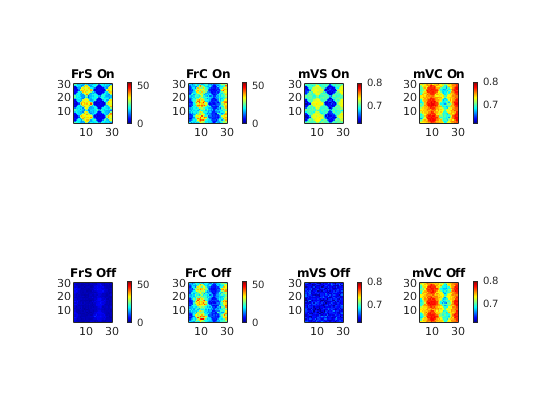

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates:S
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrSOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOnPixMat); title('FrS On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrSOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOffPixMat); title('FrS Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

% Firing rates: C
subplot 242
[FrCOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOnPixMat); title('FrC On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 246
[FrCOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOffPixMat); title('FrC Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% mVs: S
OnmVPhase = double(OnmV);
OnmVPhase(~OnmV) = nan;
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

subplot 243
[mVSOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOnPixMat); title('mVS On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

OffmVPhase = double(OffmV);
OffmVPhase(~OffmV) = nan;
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

subplot 247
[mVSOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOffPixMat); title('mVS Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

% mVs: C
subplot 244
[mVCOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOnPixMat); title('mVC On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

subplot 248
[mVCOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOffPixMat); title('mVC Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)



% % mGs
% subplot 243
% GEEOn = GE_E; GEEOn = GEEOn.*OnmVPhase;
% GEEOn_temp = nanmean(GEEOn(:,SmallWinRange),2);
% [GEEOnPixMat,~] = NeuVec2Pixel(GEEOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEEOnPixMat); title('GEE On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 247
% GEEOff = GE_E; GEEOff = GEEOff.*OffmVPhase;
% GEEOff_temp = nanmean(GEEOff(:,SmallWinRange),2);
% [GEEOffPixMat,~] = NeuVec2Pixel(GEEOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEEOffPixMat); title('GEE Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 244
% GEIOn = GE_I; GEIOn = GEIOn.*OnmVPhase;
% GEIOn_temp = nanmean(GEIOn(:,SmallWinRange),2);
% [GEIOnPixMat,~] = NeuVec2Pixel(GEIOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEIOnPixMat); title('GEI On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 248
% GEIOff = GE_I; GEIOff = GEIOff.*OffmVPhase;
% GEIOff_temp = nanmean(GEIOff(:,SmallWinRange),2);
% [GEIOffPixMat,~] = NeuVec2Pixel(GEIOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEIOffPixMat); title('GEI Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])

Figure for All Average

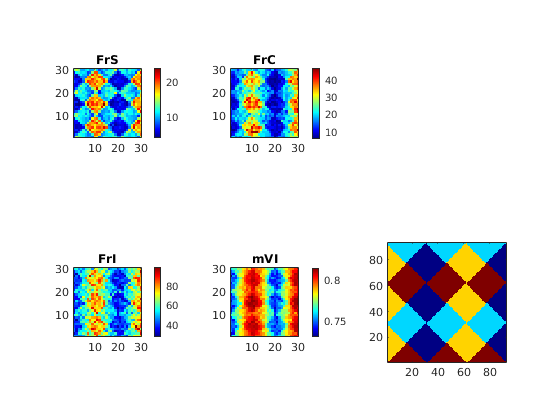

hFrVAll = figure('Name','Field_f&V');
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
%FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

subplot 231
[FrSPixMat,NnSPixel] = NeuVec2Pixel(FrE_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSPixMat); title('FrS')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar
subplot 232
[FrCPixMat,NnCPixel] = NeuVec2Pixel(FrE_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCPixMat); title('FrC')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
% subplot 233
% imagesc(OD_EMap);axis square
% set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

Complex % Simple spikes

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
hSpCount = figure('Name','SpCountE')

hSpCount =   Figure (7: SpCountE) with properties:

      Number: 7
        Name: 'SpCountE'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


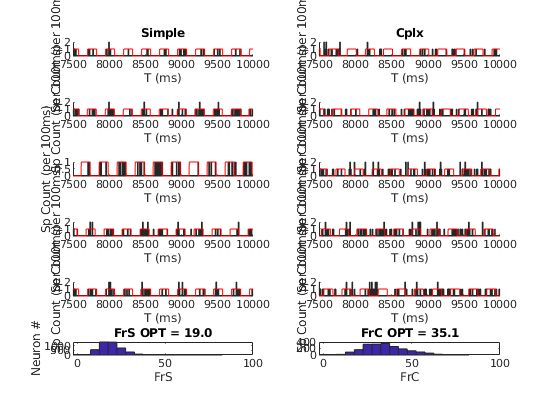

USE = [1,50,300,1000 1500];
for subInd = 1:5
    subplot(6,2,2*subInd-1)
    NeuInd = OPTS(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    if subInd ==1
        title('Simple')
    end
    
    subplot(6,2,2*subInd)
    NeuInd = OPTC(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    
    if subInd ==1
        title('Cplx')
    end
    
end
OPTS = OptE & ~EcplxInd;
OPTC = OptE & EcplxInd;
subplot(6,2,11)   
hist(FrE_temp(OPTS),0:5:80)
title(sprintf('FrS OPT = %.1f', mean(FrE_temp(OPTS))))
xlabel('FrS'); ylabel('Neuron #')
subplot(6,2,12)   
hist(FrE_temp(OPTC),0:5:80)
title(sprintf('FrC OPT = %.1f', mean(FrE_temp(OPTC))))
xlabel('FrC')

%save('DriveWkSp.mat')

Voltage Traces of S Cells

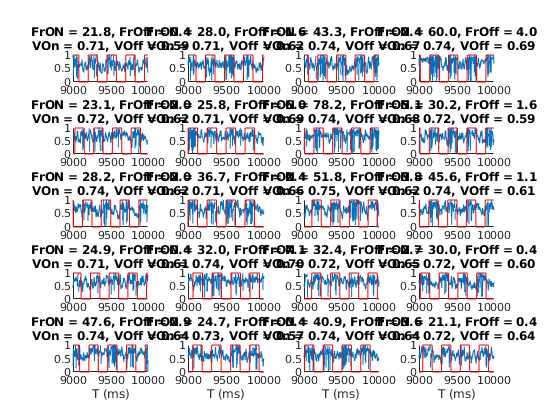

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);
hSpCount = figure('Name','SpCountE');
USE = 1:200:4001;
for subInd = 1:length(USE)-1
    subplot(5,4,subInd)
    NeuInd = OPTS(USE(subInd));
    hold on
    plot(StatWin(1:WinNum),mVE(NeuInd,:))
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-1000 T])
    if ceil(subInd/4) == 5
    xlabel('T (ms)')   
    end
    title(sprintf(['FrON = %.1f, FrOff = %.1f\n',...
                   'VOn = %.2f, VOff = %.2f'],...
                   FrEOn_temp(NeuInd), FrEOff_temp(NeuInd), ...
                   mVEOn_temp(NeuInd), mVEOff_temp(NeuInd)))
       
end

## MF linear equation for pixels: 1 Matrices

clear ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
      mVE mVEOff mVEOn mVI

PixNum = NPixX*N_HC * NPixY*N_HC;
% First, get connectivity matrix between Pixels
C_SS_Pixel_Us = zeros(PixNum); C_CS_Pixel_Us = zeros(PixNum);
C_SC_Pixel_Us = zeros(PixNum); C_CC_Pixel_Us = zeros(PixNum);
C_SI_Pixel_Us = zeros(PixNum); C_CI_Pixel_Us = zeros(PixNum);
C_IS_Pixel_Us = zeros(PixNum); C_IC_Pixel_Us = zeros(PixNum);
C_II_Pixel_Us = zeros(PixNum);
% look into std as well
% C_EE_Pixelstd = zeros(PixNum);
% C_EI_Pixelstd = zeros(PixNum);
% C_IE_Pixelstd = zeros(PixNum);
% C_II_Pixelstd = zeros(PixNum);
tic
AA = PixNum;
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_SS_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_SS_Fix_Bd(NnSPixel.Vec == PixIndPost, NnSPixel.Vec == PixIndPre),2));
        C_SC_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_SC_Fix_Bd(NnSPixel.Vec == PixIndPost, NnCPixel.Vec == PixIndPre),2));
        C_CS_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_CS_Fix_Bd(NnCPixel.Vec == PixIndPost, NnSPixel.Vec == PixIndPre),2));
        C_CC_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_CC_Fix_Bd(NnCPixel.Vec == PixIndPost, NnCPixel.Vec == PixIndPre),2));
        C_SI_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_SI_Fix_Bd(NnSPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_CI_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_CI_Fix_Bd(NnCPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IS_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_IS_Fix_Bd(NnIPixel.Vec == PixIndPost, NnSPixel.Vec == PixIndPre),2));
        C_IC_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_IC_Fix_Bd(NnIPixel.Vec == PixIndPost, NnCPixel.Vec == PixIndPre),2));
        C_II_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
%         C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE_Fix_Bd(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
%         C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI_Fix_Bd(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
%         C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE_Fix_Bd(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
%         C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


toc

Elapsed time is 49.641949 seconds.


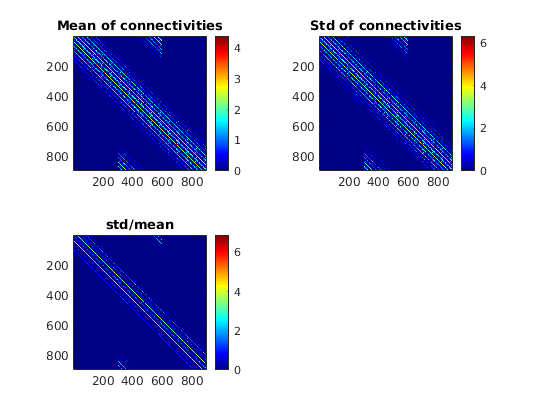

% C_EE_Pixel_Us = sparse(C_EE_Pixel);
% C_IE_Pixel_Us = sparse(C_IE_Pixel);
% C_EI_Pixel_Us = sparse(C_EI_Pixel);
% C_II_Pixel_Us = sparse(C_II_Pixel);
save([SaveFolder 'ConnPixel_Cconst.mat'], 'C_SS_Pixel_Us','C_CS_Pixel_Us',...
                                   'C_SC_Pixel_Us','C_CC_Pixel_Us',...
                                   'C_SI_Pixel_Us','C_CI_Pixel_Us',...
                                   'C_IS_Pixel_Us','C_IC_Pixel_Us',...
                                   'C_II_Pixel_Us')
load([SaveFolder 'ConnPixel_Cconst.mat'])
% Present connectivity mats
figure
subplot 221
imagesc(C_SS_Pixel_Us)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_CS_Pixel_Us)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_CI_Pixel_Us)
axis square
colorbar
title('std/mean')

## Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
      C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
      C_SS_Fix_Bd C_SC_Fix_Bd C_CS_Fix_Bd C_CC_Fix_Bd...
      C_SI_Fix_Bd C_CI_Fix_Bd C_IS_Fix_Bd C_IC_Fix_Bd...
      COpt_Ind SOpt_Ind scatterCOpt scatterSOpt...
      ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
      mVE mVEOff mVEOn mVI

MF linear equation for pixels: 2 MF Eqns

load([SaveFolder 'ConnPixel.mat'])

PixNum = NPixX*N_HC * NPixY*N_HC;
FrSPixVec    = reshape(FrSPixMat,  PixNum,1);
FrSOnPixVec  = reshape(FrSOnPixMat,PixNum,1);
FrSOffPixVec = reshape(FrSOffPixMat,PixNum,1);
FrCPixVec    = reshape(FrCPixMat,  PixNum,1);
FrCOnPixVec  = reshape(FrCOnPixMat,PixNum,1);
FrCOffPixVec = reshape(FrCOffPixMat,PixNum,1);
FrIPixVec    = reshape(FrIPixMat,  PixNum,1);

mVSOnPixVec  = reshape(mVSOnPixMat,PixNum,1);
mVSOffPixVec = reshape(mVSOffPixMat,PixNum,1);
mVCOnPixVec  = reshape(mVCOnPixMat,PixNum,1);
mVCOffPixVec = reshape(mVCOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_SOn_Pixel = zeros(PixNum,1);
lambda_SOff_Pixel = zeros(PixNum,1);
lambda_COn_Pixel = zeros(PixNum,1);
lambda_COff_Pixel = zeros(PixNum,1);
L6S_Pixel = zeros(PixNum,1);
L6C_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
lambda_SOn_drive = lambda_EOn_drive(~EcplxInd); lambda_COn_drive = lambda_EOn_drive(EcplxInd);
lambda_SOff_drive = lambda_EOff_drive(~EcplxInd); lambda_COff_drive = lambda_EOff_drive(EcplxInd);
rS_L6_Drive = rE_L6_Drive(~EcplxInd); rC_L6_Drive = rE_L6_Drive(EcplxInd);
for PixInd = 1:PixNum
    lambda_SOn_Pixel(PixInd)  = mean(lambda_SOn_drive(NnSPixel.Vec == PixInd));
    lambda_SOff_Pixel(PixInd) = mean(lambda_SOff_drive(NnSPixel.Vec == PixInd));
    lambda_COn_Pixel(PixInd)  = mean(lambda_COn_drive(NnCPixel.Vec == PixInd));
    lambda_COff_Pixel(PixInd) = mean(lambda_COff_drive(NnCPixel.Vec == PixInd));
    L6S_Pixel(PixInd) = mean(rS_L6_Drive(NnSPixel.Vec == PixInd));
    L6C_Pixel(PixInd) = mean(rC_L6_Drive(NnCPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive_Pre;

Below need work

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + 2*PixNum;
FrPreUse = FrSOffPixVec(FrPreUseDim - 2*PixNum); 
%FrPreUse = FrEOffLIF(FrPreUseDim - PixNum); 
FrPreUse = [];


% Mats
MatSS = (S_EE*(1-p_EEFail))*full(C_SS_Pixel_Us); 
MatSC = (S_EE*(1-p_EEFail))*full(C_SC_Pixel_Us);% Need Ref here??
MatCS = (S_EE*(1-p_EEFail))*full(C_CS_Pixel_Us); 
MatCC = (S_EE*(1-p_EEFail))*full(C_CC_Pixel_Us);% Need Ref here??
MatSI = S_EI *              full(C_SI_Pixel_Us); 
MatCI = S_EI *              full(C_CI_Pixel_Us);
MatIS = S_IE *              full(C_IS_Pixel_Us);
MatIC = S_IE *              full(C_IC_Pixel_Us);
MatII = S_II *              full(C_II_Pixel_Us);
eVSOn  = (Ve-repmat(mVSOnPixVec,1,PixNum));  iVSOn  = (Vi-repmat(mVSOnPixVec,1,PixNum));
eVSOff = (Ve-repmat(mVSOffPixVec,1,PixNum)); iVSOff = (Vi-repmat(mVSOffPixVec,1,PixNum));
eVCOn  = (Ve-repmat(mVCOnPixVec,1,PixNum));  iVCOn  = (Vi-repmat(mVCOnPixVec,1,PixNum));
eVCOff = (Ve-repmat(mVCOffPixVec,1,PixNum)); iVCOff = (Vi-repmat(mVCOffPixVec,1,PixNum));
eVI    = (Ve-repmat(mVIPixVec,1,PixNum));    iVI    = (Vi-repmat(mVIPixVec,1,PixNum));
% post/pre SOn              COn              SOff             COff             I
ConnMat = [MatSS/2.*eVSOn,  MatSC/2.*eVSOn,  MatSS/2.*eVSOn,  MatSC/2.*eVSOn,  MatSI.*iVSOn;  % SOn
           MatCS/2.*eVCOn,  MatCC/2.*eVCOn,  MatCS/2.*eVCOn,  MatCC/2.*eVCOn,  MatCI.*iVCOn;  % COn
           MatSS/2.*eVSOff, MatSC/2.*eVSOff, MatSS/2.*eVSOff, MatSC/2.*eVSOff, MatSI.*iVSOff; % SOff
           MatCS/2.*eVCOff, MatCC/2.*eVCOff, MatCS/2.*eVCOff, MatCC/2.*eVCOff, MatCI.*iVCOff; % COff
           MatIS/2.*eVI,    MatIC/2.*eVI,    MatIS/2.*eVI,    MatIC/2.*eVI,    MatII.*iVI];   % I
% Leak On/Off
LeakSOn  = gL_E * (0-mVSOnPixVec)  * 1e3;
LeakCOn  = gL_E * (0-mVCOnPixVec)  * 1e3;
LeakSOff = gL_E * (0-mVSOffPixVec) * 1e3;
LeakCOff = gL_E * (0-mVCOffPixVec) * 1e3;
LeakI =    gL_I * (0-mVIPixVec)    * 1e3;
LeakV = [LeakSOn;
         LeakCOn;
         LeakSOff;
         LeakCOff;
         LeakI];
% Ext
ExtSOn  = (lambda_SOn_Pixel*S_Elgn  + rE_amb*S_amb + L6S_Pixel*S_EL6).*(Ve-mVSOnPixVec ) * 1e3;
ExtCOn  = (lambda_COn_Pixel*S_Elgn  + rE_amb*S_amb + L6C_Pixel*S_EL6).*(Ve-mVCOnPixVec ) * 1e3;
ExtSOff = (lambda_SOff_Pixel*S_Elgn + rE_amb*S_amb + L6S_Pixel*S_EL6).*(Ve-mVSOffPixVec) * 1e3;
ExtCOff = (lambda_COff_Pixel*S_Elgn + rE_amb*S_amb + L6C_Pixel*S_EL6).*(Ve-mVCOffPixVec) * 1e3;
ExtI =    (lambda_I_Pixel*S_Ilgn    + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec)    * 1e3;
ExtV = [ExtSOn;
        ExtCOn;
        ExtSOff;
        ExtCOff
        ExtI];
% Ref Vec
RefSOn = 1-FrSOnPixVec*tau_ref/1e3;
RefCOn = 1-FrCOnPixVec*tau_ref/1e3;
RefSOff = 1-FrSOffPixVec*tau_ref/1e3;
RefCOff = 1-FrCOffPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = diag([RefSOn;...
             RefCOn;...
             RefSOff;...
             RefCOff;...
             RefI]);
% L4 Frs
Fr_L4 = [FrSOnPixVec; FrCOnPixVec; FrSOffPixVec; FrCOffPixVec; FrIPixVec];

% MF Equations:
%Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
tic
    if isempty(FrPreUse)
    Fr_MFinv = (sparse(eye(5*PixNum))-RefM*ConnMat) \ (RefM * ( ExtV + LeakV));
    else
        FrPreVec = zeros(PixNum*5,1); FrPreVec(FrPreUseDim) = FrPreUse;
        DimAll = 1:PixNum*5; FrminusDim = DimAll(~ismember(DimAll,FrPreUseDim));
        FrPreReplace = RefM*ConnMat * FrPreVec; 
        % Now compute in the subspace
        FrPreMinus = FrPreReplace(FrminusDim);
        RefMMinus  = RefM(FrminusDim, FrminusDim);
        ConnMatMinus = ConnMat(FrminusDim, FrminusDim);
        ExtVMinus = ExtV(FrminusDim);
        LeakVMinus = LeakV(FrminusDim);
        Fr_MFinvMinus = (sparse(eye(length(FrminusDim)))-RefMMinus*ConnMatMinus) \ ...
                        (RefMMinus * ( ExtVMinus + LeakVMinus) + FrPreMinus);
        % make up MF output            
        Fr_MFinv = zeros(PixNum*5,1);   
        Fr_MFinv(FrminusDim) = Fr_MFinvMinus; Fr_MFinv(FrPreUseDim) = FrPreUse; 
    end
toc

Elapsed time is 0.830945 seconds.


% Err
FrErr = Fr_MFinv - Fr_L4;

Scatter MF Rslt

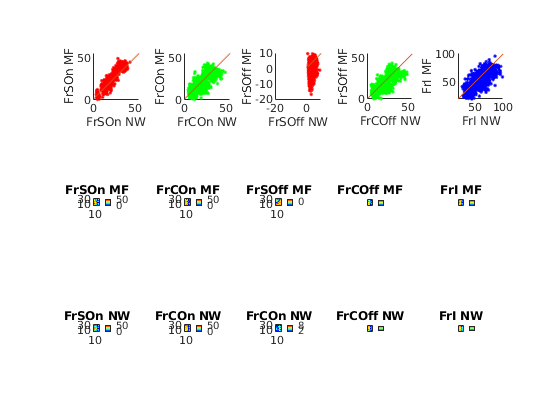

SC = Fr_MFinv;

figure('Name','FrCompare')
subplot 351
hold on
scatter(FrSOnPixVec, SC(1:PixNum),'r.')
plot(1:120, 1:120)
axis([0 55 0 55]);axis square
xlabel('FrSOn NW'); ylabel('FrSOn MF')
subplot 352
hold on
scatter(FrCOnPixVec, SC(PixNum+1:2*PixNum),'g.')
plot(1:120, 1:120)
axis([0 55 0 55]);axis square
xlabel('FrCOn NW'); ylabel('FrCOn MF')

subplot 353
hold on
scatter(FrSOffPixVec, SC(2*PixNum+1:3*PixNum),'r.')
plot(1:120, 1:120)
axis([-20 10 -20 10]); axis square
xlabel('FrSOff NW'); ylabel('FrSOff MF')
subplot 354
hold on
scatter(FrCOffPixVec, SC(3*PixNum+1:4*PixNum),'g.')
plot(1:120, 1:120)
axis([0 55 0 55]); axis square
xlabel('FrCOff NW'); ylabel('FrSOff MF')

subplot 355
hold on
scatter(FrIPixVec, SC(4*PixNum+1:5*PixNum),'b.')
plot(1:120, 1:120)
axis([20 100 20 100]); axis square
xlabel('FrI NW'); ylabel('FrI MF')

subplot 356
ShowField(SC(1:PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrSOn MF')
caxis([0 55])

subplot 357
ShowField(SC(PixNum+1:2*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrCOn MF')
caxis([0 55])

subplot 358
ShowField(SC(2*PixNum+1:3*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrSOff MF')
%caxis([0 55])

subplot 359
ShowField(SC(3*PixNum+1:4*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrCOff MF')
caxis([0 55])

subplot(3, 5, 10)
ShowField(SC(4*PixNum+1:5*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrI MF')
caxis([20 100])

subplot(3,5,11)
ShowField(FrSOnPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrSOn NW')
caxis([0 55])

subplot(3,5,12)
ShowField(FrCOnPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrCOn NW')
caxis([0 55])

subplot(3,5,13)
ShowField(FrSOffPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrCOn NW')
%caxis([0 55])

subplot(3,5,14)
ShowField(FrCOffPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrCOff NW')
caxis([0 55])

subplot(3,5,15)
ShowField(FrIPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrI NW')
caxis([20 100])

Plot MF Rslt

EPixRange = [0 40];
IPixRange = [10 120]

figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)
caxis(EPixRange);

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)
caxis(IPixRange);

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = (reshape(Fr_MFinv(1:PixNum),NPixY*N_HC,NPixX*N_HC) + ...
               reshape(Fr_MFinv(PixNum+1:2*PixNum),NPixY*N_HC,NPixX*N_HC))/2;
imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)
caxis(EPixRange);

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(2*PixNum+1:end),NPixY*N_HC,NPixX*N_HC)
imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)
caxis(IPixRange);

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
hold on
plot(1:120, 1:120)
scatter(FrEPixVec,(Fr_MFinv(1:PixNum) + Fr_MFinv(PixNum+1:2*PixNum))/2,'r.')
axis([EPixRange EPixRange])
axis square
xlabel('FrE'); ylabel('FrE_{MF}')

subplot 248
hold on
plot(1:120, 1:120)
scatter(FrIPixVec,Fr_MFinv(2*PixNum+1:end),'b.')
 axis([IPixRange IPixRange])
axis square
xlabel('FrI'); ylabel('FrI_{MF}')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?